# Laboratory 3: Di Via & Hiller-Szala

## Introduction 

In this laboratory, we address the problem of reconstructing STIX images from modulated X-ray signals. The challenge lies in recovering the original intensity distribution from limited and compressed Fourier components.

### Study Case and Description of the Instrument

Solar flares are powerful bursts of energy resulting from the Sun's complex magnetic activity. The Sun's magnetic field, changing in time, creates regions of intense electromagnetic force. In the solar corona, where the plasma is highly ionized, free electrons are accelerated by the electromagnetic forces along these magnetic field lines. As the electrons spiral along the magnetic field, they are directed toward the denser chromosphere. Upon reaching the chromosphere, these high-energy particles encounter increasingly dense and heavy atmospheric layers. The collisions between the electrons and the ions in the chromosphere slow down the particles, a process known as **bremsstrahlung** ("braking radiation"). During these interactions, the electrons emit high-energy X-ray photons, producing two localized sources of radiation visible in high-energy X-ray images. The emitted X-rays travel back into the corona, heating the plasma further. However, this heating is no longer localized to the two emission spots; instead, the energy spreads across a larger area of the corona with lower intensity.

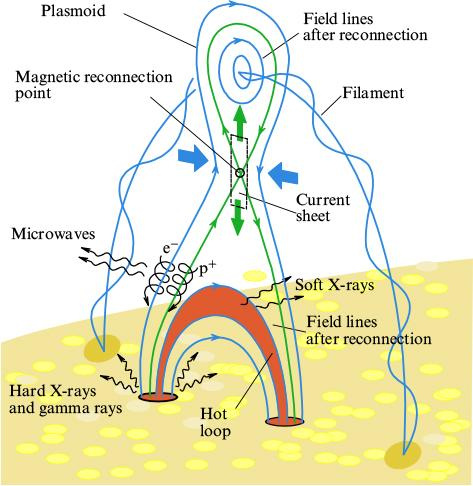               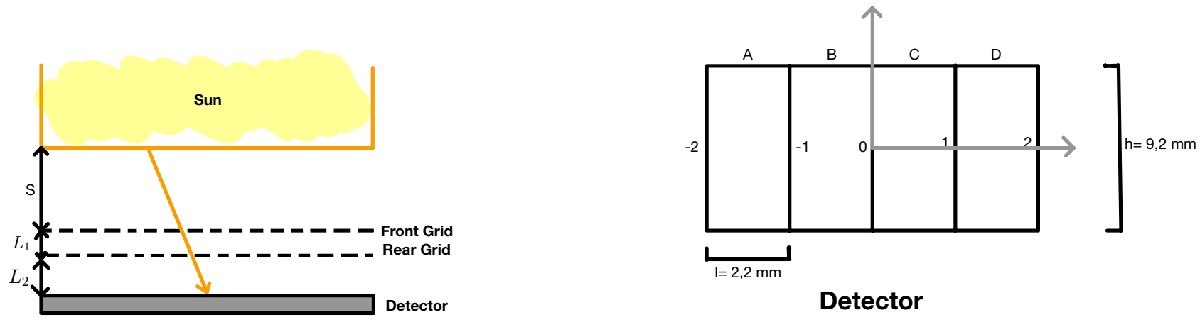

The **Spectrometer/Telescope for Imaging X-rays (STIX)** onboard ESA’s Solar Orbiter observes X-rays from space, overcoming atmospheric absorption. STIX operates at a distance S of approximately $10^8$ km from the Sun and uses a system of grids and detectors to capture X-ray data efficiently.

The instrument consists of a **front grid** and a **rear grid**, separated by a distance $L_1=55$ cm. Additionally, the rear grid is separated from the **detector array** by $L_2=4.7$ cm. The grids are slightly rotated relative to each other, ensuring that they do not overlap perfectly. This arrangement causes the X-rays passing through the grids to produce **Moiré patterns (**shadow-like interference fringes) on the detector. STIX contains 30 such grid-detector systems, each designed to generate unique moiré patterns corresponding to different **Fourier components** of the X-ray intensity distribution with a specific spatial frequency, enabling the reconstruction of detailed images. The detector, viewed from above, is structured with a height of 9.2 mm and features four distinct regions, A, B, C, and D, separated by 2.2 mm. STIX uses Fourier transform-based data compression, transmitting only essential Fourier components of the observed X-ray emission components to Earth, reducing data volume while retaining the essential information needed for image reconstruction.

## Mathematical Background

STIX, captures X-ray visibilities by measuring the moiré patterns formed by X-ray photons passing through pairs of grids. These visibilities correspond to specific spatial frequencies of the X-ray intensity distribution of the solar source. The signal formation process is mathematically described in this section.

Let  $\phi(x, y)$ be the spatial intensity distribution of the X-ray source on the Sun, where $(x, y)$ are the coordinates on the source plane. The goal is to measure this distribution indirectly using visibilities. The front and rear grids  in the telescope acts as a spatial modulator of the incoming X-ray photons defining a specific spatial frequency $(u, v)$ in the Fourier domain. 

The detector measures the modulated intensity, which corresponds to the integral 

$V(u, v) = \int\int \phi(x, y) e^{2i \pi(ux + vy)} dx \, dy$, 

where$V(u, v)$ is the** Fourier visibility** at the spatial frequency $(u, v)$. Each pair of grids measures one Fourier component of the source intensity distribution $\phi(x,y)$. The moiré patterns formed on the detector encode variations in intensity proportional to these Fourier components. Segmented detector regions (e.g., A, B, C, D in STIX) capture these variations, encoding the amplitude and phase of $V(u,v)$. By combining measurements from all 30 grid-detector systems, STIX samples up to 60 spatial frequencies $(u,v)$. To recover the flux $\phi(x, y)$ of the X-ray source an inverse Fourier transform is required:

$\phi(x, y) = \int\int V(u, v) e^{-2\pi i (ux + vy)} \, du \, dv$.

However, due to the instrument design, only a limited number of Fourier points $N_v$ (up to 60) are available. This limited sampling creates challenges in reconstructing the image. We recall that the image formation model can be expressed as:

- $g(\underline{x})=K * f(\underline{x})=\int \int_{\mathbb{R}^2} f(\underline{x}') K(\underline{x}-\underline{x}')d\underline{x}'$ in physical space;

- $\hat{g(\underline{\omega})}=H(\underline{\omega}) \cdot \hat{f}(\underline{\omega})$ in the frequency space, where $\hat{g}=\mathcal{F}(g)$, $H=\mathcal{F}(K)$ and $\hat{f}=\mathcal{F}(f)$.

Given the $N_v$ sampled Fourier points, we can define the** Transfer Function** $H(u,v):=\begin{cases} 1 \quad \text{if } (u,v) \in \mathcal{M}\\ 0 \quad \text{if } (u,v) \notin \mathcal{M} \end{cases}$  where $\mathcal{M}:=\{(u_j,v_j)| j=0,\cdots, N_v-1\}$. 

So we know that image formation in STIX is given by $V_j(u,v)=H(u,v) \cdot V(u,v)$. 

To recover the original flux $\phi=\mathcal{F}^{-1}(V)$ we need to compute the** Back Projection **$\phi_{BP}=\mathcal{F}^{-1}(V_j)=\sum_{j=0}^{N_v-1} V_j \cdot e^{-2 \pi i (u_j x + v_j y)}$ and the** PSF** $K=\mathcal{F}^{-1}(H)$.

By defining a $N \times M$ grid, we discretize them obtaining respectively the **Dirty Map** $DM(x_m,y_n)=\sum_{j=0}^{N_v-1} V_j \cdot e^{-2 \pi i (u_j x_m + v_j y_n)}$ and the **Dirty Beam** $DB(x_m,y_n)=\sum_{j=0}^{N_v-1} e^{-2 \pi i (u_j x_m + v_j y_j)}$ for all $m=0, \cdots, M-1$ and for all $n=0, \cdots, N-1$. 

So the estimation of the flux $\phi$ can be reconducted to the deconvolution problem $\phi_{BP}(x,y)=\int \int K(x-x', y-y') \phi(x',y') dx' dy'$ knowing DM and DB.

To solve this problem we address to the** Clean Algorithm**.

### Clean Algorithm 

The Clean Algorithm is designed to iteratively estimate the flux distribution. 

We assume the flux is represented as the superposition of Q of point sources $\phi_q$ at position $(x_q, y_q)$ for all $q=1, \cdots, Q$.

Under the hypothesis that PSF $K(x,y) \longrightarrow 0$ rapidly, it's possible to define $\phi_{\max}=\phi_Q \cdot K_{\max}$and to recover the original flux by cleaning the dirty map removing contribution of PSF on each source $\phi_{BP}'(x,y)=\phi_{BP}(x,y)-\phi_Q K(x-x_Q, y-y_Q)$. After $Q$ iterations, the dirty map would theoretically become null, revealing both the flux and the number of sources. In practice, however, this assumption is unrealistic. Instead, given the estimations DM and DB, the CLEAN algorithm is implemented as follows:

- Let $\gamma \in [0,1]$ be a ganing factor and $t=0$ denote the number of iterations, with initial values $DM^{(0)}=DM$ (dirty map) and $CC^{(0)}=0$ (the cleaned component map) for all $x,y$.

- At each iteration $t\geq1$,

- Identify the brightest point in the dirty map:

$\phi_{\max}^{(t)}=\max(DM^{(t-1)})$ and $(x_{\max}^{(t)}, y_{\max}^{(t)})=\arg \max_{(x,y)}(DM^{(t-1)})$;

- Subtract a shifted version of the dirty beam centered on this point:

$DM^{(t)}=DM^{(t-1)}-\gamma \frac{\phi_{\max}^{(t)}}{\max(DB)}DB(x-x_{\max}^{(t)}, y-y_{\max}^{(t)})$;

- Add the flux to a model image:

$CC^{(t)}=CC^{(t-1)}+\gamma \frac{\phi_{\max}^{(t)}}{\max(DB)} \delta(x-x_{\max}^{(t)}, y-y_{\max}^{(t)})$.

The process stops when the remaining dirty map consists only of noise. The algorithm gradually cleans the back-projected image, iteratively removing blurring contributions and refining the cleaned component map and if $PSF(x) \longrightarrow 0$ quickly and $\gamma = 1$, this formulation matches the idealized case.

### Clean Beam and Clean Map

 The **Clean Beam** is an ideal PSF approximated as a 2D Gaussian where its peak aligns with the peak of the dirty beam and its standard deviation is derived from the** full width at half maximum (FWHM)** of the dirty beam’s central peak as it follows:

$CB(x, y) = \frac{1}{2\pi \sigma_x \sigma_y} \exp\left(-\frac{1}{2} \left[\frac{(x - \mu_x)^2}{\sigma_x^2} +\frac{(y - \mu_y)^2}{\sigma_y^2}\right]\right)$,

 with $\sigma_{x,y} = \frac{\text{FWHM}}{2\sqrt{2\ln 2}}$ and  $( \mu_x, \mu_y)$ the coordinates of the dirty beam's peak. 

Eventually, we obtain the **Clean Map** by convolving the Cleaned Component Map with the Clean Beam: $CM= CC * CB$.

This step is a relaxation of the point-source assumption, smoothing the reconstructed flux and producing a realistic representation of the original source distribution.

## Laboratory Introduction

In this lab, we focus on reconstructing an X-ray image of a solar flare that occurred on April 9, 2022, using visibility data provided by STIX.

clear all; clc; close all;

## Step 0: Importing Data 

The dataset used in this exercise, stored in *data2.xlsx*, contains visibilities recorded in the 6–10 keV energy range. These visibilities, encoding spatial information about X-ray emissions, are later analyzed to reconstruct a high-resolution image of a solar flare. The input data is organized into 24 rows and 4 columns:

- Column 1: Spatial frequencies $u_j$ $(j=1, \dots, 24)$;

- Column 2: Spatial frequencies $v_j$ $(j=1, \dots, 24)$;

- Column 3: Real part of visibilities $V(u_j, v_j)$;

- Column 4: Imaginary part of visibilities $V(u_j, v_j)$.

We imported the visibility data directly as complex numbers.

%-------------------------------------------------------DATA LOADING---------------------------------------

% Loading data
data=readmatrix("data2.xlsx");

% Extracting data
u=data(:,1); 
v=data(:,2); 
Vis=data(:,3)+1i*data(:,4); 

## Step I: Data Analysis

The sampled points $(u,v)$ follow a spiral pattern, which can be visualized to better understand the spatial frequency coverage. The symmetry property of visibilities, given by $V(-\xi)=\overline{V(\xi)}$ allows us to double the available 24 sampled points by mirroring them about the origin, providing more comprehensive spatial information for image reconstruction.

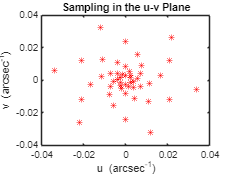

%-------------------------------------------------------DATA VISUALIZATION---------------------------------------

% Doubling the sampled points
u_total=[u; -u];
v_total=[v; -v];
Vis_total=[Vis; conj(Vis)]; 

% Clearing unused variables 
clear u; clear v; clear Vis; 

% Plotting uv plane
figure;
plot(u_total, v_total, 'r*');
title('Sampling in the u-v Plane');
xlabel('u (arcsec^{-1})'); ylabel('v (arcsec^{-1})');

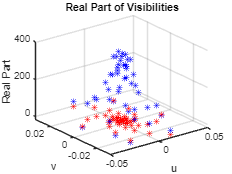


% Plotting real part of visibilities
figure;
scatter3(u_total, v_total, real(Vis_total), 'b*');
hold on;
scatter3(u_total, v_total, 0, 'r*');
title('Real Part of Visibilities');
xlabel('u');ylabel('v');zlabel('Real Part');

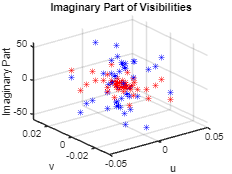


% Plotting imaginary part of visibilities
figure;
scatter3(u_total, v_total, imag(Vis_total), 'b*');
hold on;
scatter3(u_total, v_total, 0, 'r*');
title('Imaginary Part of Visibilities');
xlabel('u');ylabel('v');zlabel('Imaginary Part');

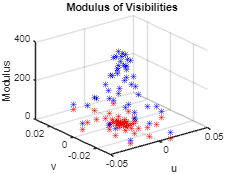


% Plotting modulus of visibilities
figure;
scatter3(u_total, v_total, abs(Vis_total), 'b*');
hold on;
scatter3(u_total, v_total, 0, 'r*');
title('Modulus of Visibilities');
xlabel('u');ylabel('v');zlabel('Modulus');

## Step II: Reconstruction

Using the available visibility dataset, we reconstruct the X-ray image of the flare using the CLEAN algorithm.

### Dirty Map

Now, we display the Dirty Map obtained from the visibilities. First, we define a $128 \times 128$ grid covering the spatial domain, then compute the Dirty Map, as described in the mathematical background section$DM(x_m,y_n)=\sum_{j=0}^{N_v-1} V_j \cdot e^{-2 \pi i (u_j x_m + v_j y_n)}$.  After calculating the Dirty Map, we rotate it by 90° counterclockwise to align it with the STIX reference frame, which is rotated with respect to the Sun's coordinate system. We then plot both the real and imaginary parts of the Dirty Map. It's possible to notice that the real part carries the primary information while the imaginary part is negligible.

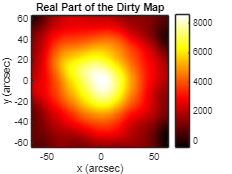

%-------------------------------------------------------DIRTY MAP---------------------------------------

% Defining a grid
x1=linspace(-64, 63, 128);  
y1=linspace(63, -64, 128); 
[X1, Y1]=meshgrid(x1, y1); 

% Computing the Dirty Map
DM=sum(Vis_total.*exp(-2*1i*pi*(u_total*X1(:).'+v_total*Y1(:).')), 1);  
DM=reshape(DM, 128, 128);
DM=imrotate(DM, 90);

% Plotting the real part of the Dirty Map
figure;
imagesc(x1, y1, real(DM)); 
colorbar; colormap(hot);
title('Real Part of the Dirty Map');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');  

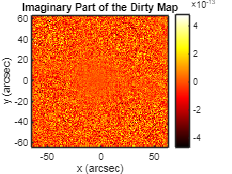


% Plotting the imaginary part of the Dirty Map
figure;
imagesc(x1, y1, imag(DM));
colorbar; colormap(hot);
title('Imaginary Part of the Dirty Map');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal'); 

### Transfer Function

Given the 48 sampled Fourier points, we plot the transfer function $H(u,v):=\begin{cases} 1 \quad \text{if } (u,v) \in \mathcal{M}\\ 0 \quad \text{if } (u,v) \notin \mathcal{M} \end{cases}$  where $\mathcal{M}:=\{(u_j,v_j)| j=0,\cdots, 47\}$. 

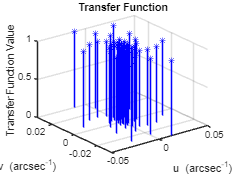

%-------------------------------------------------------TRANSFER FUNCTION---------------------------------------
% Plotting Transfer Function
figure;
stem3(u_total,v_total, ones(length(u_total),1) , 'b*');
title('Transfer Function');
xlabel('u (arcsec^{-1})'); ylabel('v (arcsec^{-1})');zlabel('Transfer Function Value');

### Dirty Beam

Now we define the Dirty Beam, the discrete version of the Transfer Function shown in the Mathematical Background section. The process is similar to the Dirty Map construction but with a larger Field of View (FOV) and grid dimensions. Specifically, the FOV is doubled to $256 \times 256$ arcsec, and the grid size is doubled. Additionally, we normalize the Dirty Beam to ensure that the maximum value is 1.

These steps are crucial for the Clean Algorithm, requiring to shift the Dirty Beam (aligning its center to the maximum value of the Dirty Map) and to compute the $\max(DB)$ value: 

$DM^{(t)}=DM^{(t-1)}-\gamma \frac{\phi_{\max}^{(t)}}{\max(DB)}DB(x-x_{\max}^{(t)}, y-y_{\max}^{(t)})$;

The Dirty Beam is then rotated by 90° to align with the reference frame.

Next, we plot both the real and imaginary parts of the Dirty Beam. Again, the real part contains the primary information, while the imaginary part is negligible. 

From a 3D plot of the real part of the Dirty Beam it's also possible to notice that STIX PSF doesn't satisfy the ideal hypothesis $PSF(x) \longrightarrow 0$ quickly.

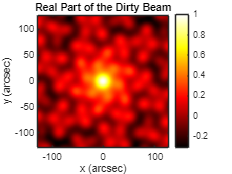

%-------------------------------------------------------DIRTY BEAM---------------------------------------

% Defining a grid
x2=linspace(-128, 127, 256);  
y2=linspace(127, -128, 256); 
[X2, Y2]=meshgrid(x2, y2); 

% Computing the Dirty Beam
DB=sum(exp(-2*1i*pi*(u_total*X2(:)'+v_total*Y2(:)')), 1);  
DB=reshape(DB, 256, 256);
DB=DB/max(abs(DB(:))); 
DB=imrotate(DB,90);

% Plotting the real part of the Dirty Beam
figure;
imagesc(x2, y2, real(DB)); 
colorbar; colormap(hot);
title('Real Part of the Dirty Beam');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');  

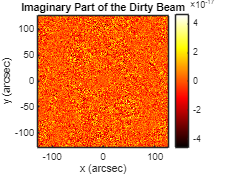


% Plotting the imaginary part of the Dirty Beam
figure;
imagesc(x2, y2, imag(DB));
colorbar; colormap(hot);
title('Imaginary Part of the Dirty Beam');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal'); 

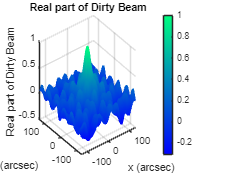


% Plotting the real part of the Dirty Beam in 3D
figure;
mesh(X2,Y2,real(DB));
title('Real part of Dirty Beam');
colorbar; colormap('hot');
xlabel('x (arcsec)'); ylabel('y (arcsec)'); zlabel('Real part of Dirty Beam');

### Clean Algorithm

Now it's possible to apply the CLEAN algorithm, described in the Mathematical Background section, to the Dirty Map and the Dirty Beam to reconstruct the X-ray image of the solar flare. 

We decided the algorithm to continue iterating until the maximum value of the dirty map falls below the threshold (th=2000) or the maximum number of iterations (max_iterations=300) is reached. 

%-------------------------------------------------------CLEAN ALGORITHM---------------------------------------

% Running the Clean Algorithm with parameters: 
% max_iterations=300; 
% gamma=0.01;
% th=2000;

[DM_final, CC_final, DB_shifted]=clean_algorithm(DM, DB, 300, 0.01, 2000);

Convergence reached in 258 iterations.


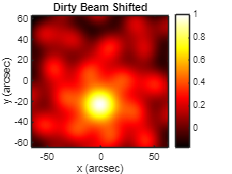


%-------------------------------------------------------PLOTTING---------------------------------------

% Plotting the real part of the Dirty Beam shifted at the final iteration
figure;
imagesc(x1,y1, real(DB_shifted));
colorbar; colormap(hot);
title('Dirty Beam Shifted');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');  

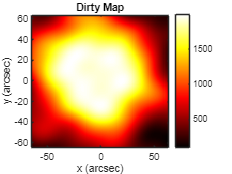


% Plotting real part of the Dirty Map at the final iteration
figure;
imagesc(x1,y1,real(DM_final));
colorbar; colormap(hot);
title('Dirty Map');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');

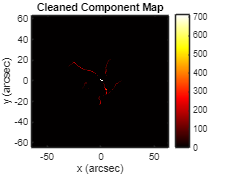


% Plotting the real part of the Cleaned Component at the final iteration
figure;
imagesc(x1,y1,real(CC_final));
colorbar; colormap(hot);
title('Cleaned Component Map');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');   

We notice that 258 iterations are required for the algorithm to converge with a $\gamma=0.01$ value and the Cleaned Component Map presents the loop shape expected.

### Clean Beam and Clean Map 

In this section, we define and compute the **Clean Beam, **modeled as a Gaussian distribution as described in the Mathematicl Background section. First we plot the sections of the Dirty Beam along the x=0 and y=0 axes to visualize its behavior at these central lines.  The FWHM value is approximately 34 arcseconds, but in STIX, it is standard practice to use the 60% height rather than the typical 50% for FWHM. This adjustment accounts for the instrument's broader response at higher energies, which results in a value of 28 arcseconds in this case.

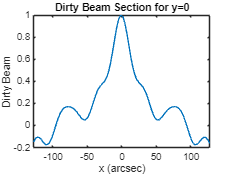

%-------------------------------------------------------SECTION PLOT AND FWHM---------------------------------------

% Axes y=0
I_y0=find(y2==0);
figure;
plot(x2, real(DB(I_y0,:)));
title('Dirty Beam Section for y=0')
xlabel('x (arcsec)'); ylabel('Dirty Beam');

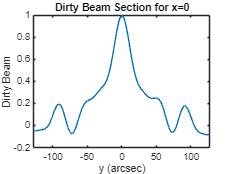


% Axes x=0
I_x0=find(x2==0);
figure;
plot(y2,real(DB(:,I_x0)));
title('Dirty Beam Section for x=0')
xlabel('y (arcsec)'); ylabel('Dirty Beam');


% Clearing unused variables 
clear I_y0; clear I_x0; 

We observe that. at that height, we have an isotropic Gaussian, where the distribution is symmetric in all directions, so we can model the Clean Beam as follows:

$\text{CB}(x, y) = \frac{1}{2\pi \sigma^2} \exp\left(-\frac{(x - \mu_x)^2 + (y - \mu_y)^2}{2\sigma^2}\right)$.

Later, the Clean Beam will be used to convolve the Cleaned Component Map, improving the image resolution by removing the blurring effects of the Dirty Beam.

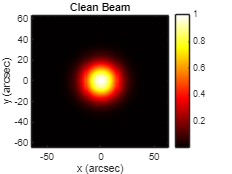

%-------------------------------------------------------CLEAN BEAM---------------------------------------

% Defining gaussian parameters
% mu_x=0; mu_y=0; % Mean
FWHM=28; sigma=FWHM/(2*sqrt(2*log(2))); % Standard Deviation

% Clean Beam as 2D Gaussian centered in 0
% CB=(1/(2*pi*sigma^2))*exp(-((X1-mu_x).^2+(Y1-mu_y).^2)/(2*sigma^2));
CB=(1/(2*pi*sigma^2))*exp(-(X1.^2+Y1.^2)/(2*sigma^2));
CB=CB/max(CB(:));

% Plotting the Clean Beam
figure;
imagesc(x1,y1, CB);
colorbar; colormap('hot');
title('Clean Beam');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
set(gca, 'YDir', 'normal');  

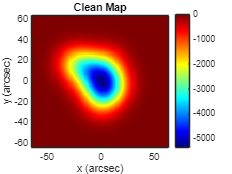


% Clearing unused variables 
% clear mu_x; clear mu_y; 
clear FWHM; clear sigma; 

%-------------------------------------------------------CLEAN MAP---------------------------------------

CM=conv2(CC_final,CB,'same');

% Plotting the Clean Map
figure;
imagesc(x1,y1,CM);
title('Clean Map');
xlabel('x (arcsec)'); ylabel('y (arcsec)');
colorbar; colormap('hot');
set(gca, 'YDir', 'normal');  

## Clean Algorithm Function

Here, we present the function used in the Clean Algorithm, as described in the Mathematical Background section. Below is a scheme that explains how to shift the Dirty Beam during the CLEAN process. The core idea is to align the center of the Dirty Beam with the position of the brightest peak in the Dirty Map, ensuring that the contribution from each source is progressively removed as the algorithm iterates.

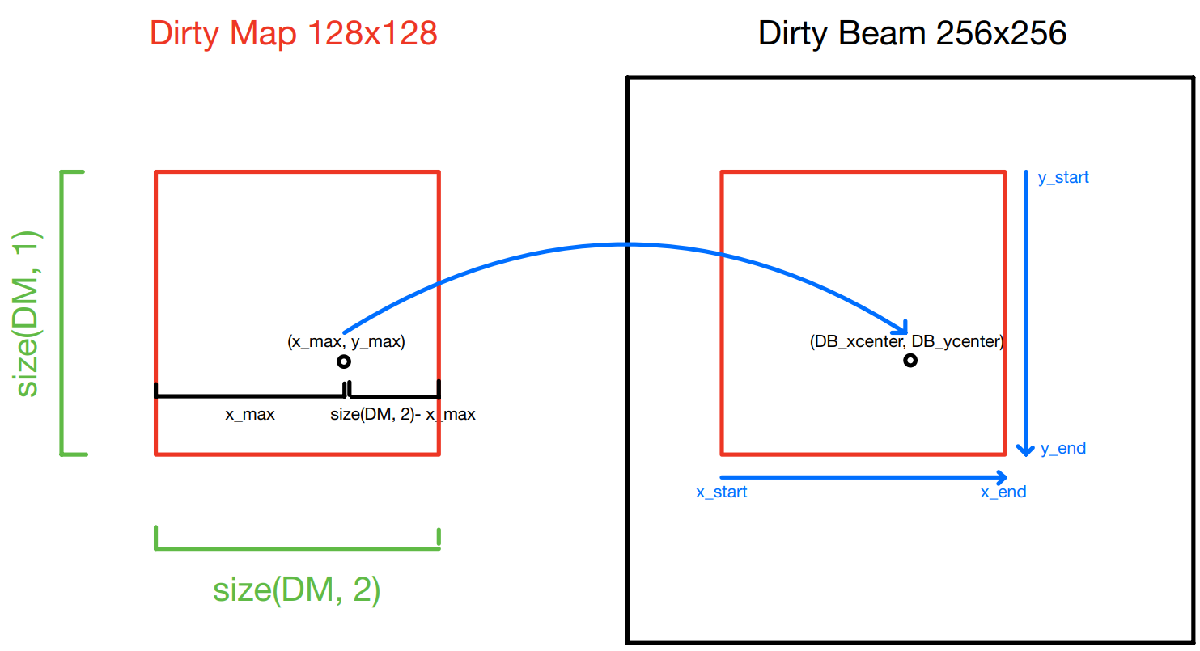

%-------------------------------------------------------CLEAN ALGORITHM FUNCTION---------------------------------------

function [DM, CC, DB_shifted]=clean_algorithm(DM, DB, max_iterations, gamma, th)

    % INPUTS:
    % DM: initial Dirty Map
    % DB: initial Dirty Beam
    % max_iterations: maximum number of iterations
    % gamma: gain factor 
    % th: threshold for stopping criteria
    
    % OUTPUTS:
    % DM: the final Dirty Map after cleaning
    % CC: the final Cleaned Component Map
    % DB_shifted: the shifted Dirty Beam during the last iteration
    % iterations: number of iterations required to converge

    %------------------------------------------INPUT CHECKS------------------------------------------------------
    
    % Dirty Map and Dirty Beam dimensional check
    if ~ismatrix(DM) || ~ismatrix(DB)
        error('Both DM and DB (first and second input) must be matrices.');
    end

    if size(DM, 1) ~= size(DM, 2) || size(DB, 1) ~= size(DB, 2)
        error('Both DM and DB (first and second input) must be square matrices.');
    end
    
    % Max iterations dimensional check
    if ~isscalar(max_iterations) || max_iterations <= 0 || floor(max_iterations)~=ceil(max_iterations)
        error('max_iterations (third input) must be a positive integer.');
    end

    % Gamma dimensional check
    if ~isscalar(gamma) || gamma < 0 || gamma > 1
        error('gamma (fourth input) must be a scalar between 0 and 1.');
    end

    % Threshold dimensional check 
    if ~isscalar(th) || th < 0
        error('th must be a non-negative scalar.');
    end

    %------------------------------------------INITIALIZATION------------------------------------------------------

    % Initialization
    CC=zeros(size(DM)); 
    Delta=CC;           

    % Finding the center of the Dirty Beam
    DB_max=max(real(DB), [], 'all');
    [DB_xcenter, DB_ycenter]=find(real(DB)==DB_max);

    %----------------------------------------------ALGORITHM-------------------------------------------------------

    % Computing the algorithm until the maximum iteration is reached
    for iterations = 1:max_iterations

        % Finding the maximum in the dirty map
        phi_max = max(real(DM), [], 'all');
        [x_max, y_max] = find(real(DM) == phi_max);

        % Computing Kronecker Delta
        Delta(x_max, y_max) = 1;

        % Checking stopping criteria
        if phi_max <= th
            break;
        end

        % Slicing the Dirty Beam to align with the Dirty Map peak
        x_start = DB_xcenter - x_max + 1;
        x_end = DB_xcenter + size(DM, 2) - x_max;
        y_start = DB_ycenter - y_max + 1;
        y_end = DB_ycenter + size(DM, 1) - y_max;

        % Shifting the Dirty Beam            
        DB_shifted = DB(x_start:x_end, y_start:y_end);

        % Computing the Dirty Map and Cleaned Component Map
        DM_new = DM - gamma * phi_max * DB_shifted;
        CC_new = CC + gamma * phi_max * Delta;

        % Updating for the next iteration
        DM = DM_new;
        CC = CC_new;
        Delta = zeros(size(DM)); 

    end

    % Display convergence message
    if iterations == max_iterations
        disp('Maximum iterations reached without convergence.');
    else
        fprintf('Convergence reached in %d iterations.\n', iterations);
    end

end
